# Lecture Notes on Statistics Problems: Chap.2: 1-7

1. Daily demand for widgets (manufactured devices) is normally distributed with a mean of 100 and a standard deviation of 15. 

a. What is the probability that the demand in a day will exceed 125? 

x = 125; mu = 100; sigma = 15;

z = (x-mu)/sigma

z = 1.6667


p = 1-normcdf(z)

p = 0.0478

b. What is the probability that the demand will be less than 75? Less than 70? 

x = 75; mu = 100; sigma = 15;

z = (x-mu)/sigma

z = -1.6667


p = normcdf(z)

p = 0.0478

By symmetry of the normal distribution, the probability below 75 is the same as the probability above 125 (both are 25 away from the mean).

c. How many widgets should be stocked to ensure with 95% probability all demands will be met? 

Rewrite 

To

z1 = norminv(0.95)

z1 = 1.6449


x1 = mu*z1*sigma

x1 = 2.4673e+03

2. LetX1, X2, ..., X10 be a random sample from a normally distributed population with mean 50 and standard deviation 4. Let $\overline{X}$ be the sample mean. 

a. Find the theoretical expected value (mean) and standard deviation of  $\overline{X}$.

Central limit theorem:

mu = 50; sigma = 4; n = 10;

sigma = sqrt((sigma^2)/n)

sigma = 1.2649

b. In Matlab, generate 10 samples from a normally distributed population with mean 50 and standard deviation 4 and calculate the sample mean, $\overline{X}$.

x = randn(1,n)*sigma + mu; % Random samples
x_bar = mean(x)

x_bar = 49.8383

s = std(x)

s = 1.5760

c. Repeat the experiment 100 times and use the commands mean and std to estimate the expected value and standard deviation of $\overline{X}$. How do the experimental values compare with the theoretical values? 

for i = 1:100
    x = randn(1,n)*sigma+mu;
    x_bar(i) = mean(x);
end

x_bar_mean = mean(x_bar)

x_bar_mean = 50.0358

x_bar_std = std(x_bar)

x_bar_std = 0.3391

3. LetX1, X2, ...,X10 be a random sample from a normal population with unknown mean $\mu$ and standard deviation 4. Let $\overline{X}$ be the sample mean, and suppose we observe = 48. 

- a. Test H0: $\mu =45$ versus H1: $\mu \ne 45$ at the 5% level. 

- b. Test H0: $\mu \le 45$ versus H1: $\mu >$45 at the 5% level. 

a.

For a two-tailed test: $2∗min\left\lbrace Pr\left(Z\ge z\right),Pr\left(Z\le z\right)\right\rbrace =2∗min\left\lbrace 1−\Phi \left(z\right)\right\rbrace$

x_hat = 48; mu = 45; sigma = 4; n = 10;

z = (x_hat-mu)/((sigma)/sqrt(n))

z = 2.3717


p = 2*min(1-normcdf(z))

p = 0.0177

The significance level is 5%, so since $p<0\ldotp 05$ the null hypothesis is rejected.

b.

For a right-tailed test: $Pr\left(Z\ge z\right)=1−Pr\left(Z\le z\right)=1−\Phi \left(z\right)$

p = 1-normcdf(z)

p = 0.0089

The significance level is 5%, so since $p<0\ldotp 05$ the null hypothesis is rejected.

4. In a random sample of 40 students graduated from Aarhus University in 2010, the average starting salary is DKK 350,000 and the standard deviation is known to be DKK 60,000. How significant is the evidence that the population mean is greater than DKK 300,000? Give a p-value. 

x_hat = 350000; mu = 300000; sigma = 60000; n = 40;

z = (x_hat-mu)/((sigma)/sqrt(n))

z = 5.2705

For a left-tailed test: $Pr\left(Z\le z\right)=\Phi \left(z\right)$


p = normcdf(z)

p = 1.0000

The null hypothesis can not be rejected because $p>0\ldotp 05$. In words, it is extremely significant that the population mean is greater than 300,000. 

5. LetX1, X2, ..., X10 be a random sample from a normal population with unknown mean $\mu$and standard deviation 4. Let $\overline{X}$ be the sample mean, and suppose we observe = 48. Find a 95% confidence interval for the population mean, $\mu$. 

Confidence level of 0.95 gives a significance level of 0.05. 

$\Phi \left(z\right)=Pr\left(Z\le z\right)=1−\frac{\alpha }{2}=1−0\ldotp 025=0\ldotp 975$ (division by 2 since it is a two-tailed test)

The z value is found $z=\Phi^{−1} \left(\Phi \left(z\right)\right)=\Phi^{−1} \left(0\ldotp 975\right)=1\ldotp 96$


$$0\ldotp 95=Pr\left(−1\ldotp 96\le Z\le 1\ldotp 96\right)=Pr\left(−1\ldotp 96\le \frac{\overline{x} −\mu }{\frac{\sigma }{\sqrt{n}}}\le 1\ldotp 96\right)$$


x_hat = 48; sigma = 4; n = 10;

lower_bound = x_hat-norminv(0.975)*sigma/sqrt(n)

lower_bound = 45.5208

upper_bound = x_hat+norminv(0.975)*sigma/sqrt(n)

upper_bound = 50.4792

6. In a random sample of 40 students graduated from Aarhus University in 2010, the average starting salary is DKK 350,000 and the standard deviation is known to be DKK 60,000. Find a 95% confidence interval for the population mean, $\mu$. 

x_hat = 350000; sigma = 60000; n = 40;

lower_bound = x_hat-norminv(0.975)*sigma/sqrt(n)

lower_bound = 3.3141e+05

upper_bound = x_hat+norminv(0.975)*sigma/sqrt(n)

upper_bound = 3.6859e+05

7. For the cup filling example, calculate the sample mean from 100 simulations of the data (similar to the Matlab code in Figure 3). For each of the 100 sample means, calculate the 95% confidence interval. How many of the intervals include the true population mean ($\mu =250$)? 

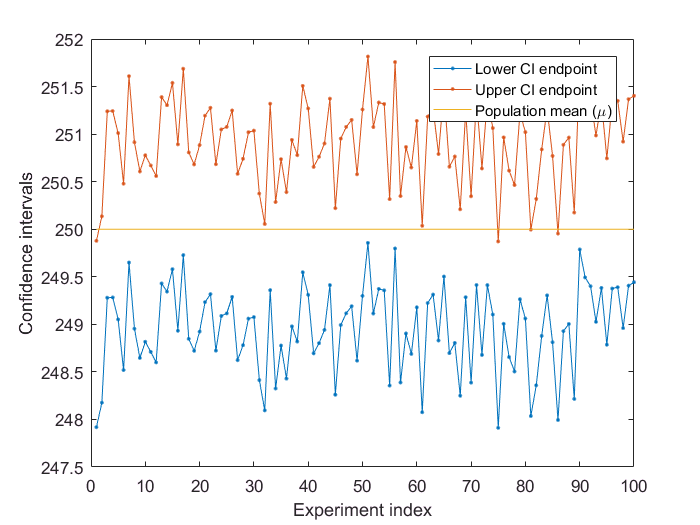

n = 25; sigma = 2.5; mu = 250; mu_obs = 250.2; mu_hat = [];

% Simulate 100 repeated experiments
for experiment = 1:100
    % 25 observations drawn randomly from the normal distribution
    X = randn(1,n)*sigma + mu;
    
    mu_low(experiment) = mean(X) - 1.96*sigma/sqrt(n);  % lower endpoint
    mu_high(experiment) = mean(X) + 1.96*sigma/sqrt(n); % upper endpoint
end


plot(1:100,mu_low,'.-',1:100,mu_high,'.-',[1 100],[mu mu])
legend('Lower CI endpoint','Upper CI endpoint','Population mean (\mu)')
xlabel('Experiment index')
ylabel('Confidence intervals')

Number of simulations that cross the true mean line does not lie within the confidence interval. (4)